# Fourier-Approximation

Wir untersuchen die Fourier-Approximation der Funktion

   
$$f(x)=1 \quad \text{für}~x \in [1,2], ~~f(x)=0\quad \text{für}~x \in [0,2 \pi]\setminus [0,1].$$


Die $n$-te Fourier-Teilsumme dieser Funktion ist (siehe Buch):

   
$$S_n(f;x)=\frac{1}{2 \pi}+ \frac{2}{\pi} \sum_{k=1}^n \frac{1}{k} \sin(\frac12 k) \left( \cos(\frac32 k) \cos (k x) + \sin(\frac32 k) \sin(k x)\right).$$


Der $n$-Wert wird gewählt:

n=50

n = 150

Die Funktion $f$ und die Fourier-Approximation $S_n(f)$ werden auf dem Interval $[0, 2 \pi]$ geplottet.

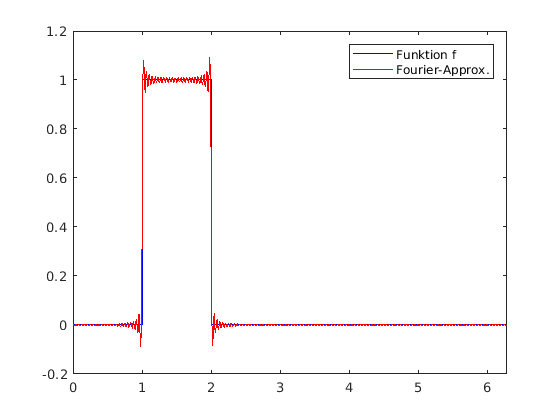

M=1001; % Anzahl Gitterpunkte für die Graphik
b=2*pi;
x=linspace(0, b, M);
y=zeros(1,M);    approx=zeros(1,M);
for i=1:M
    y(i)=f(x(i));
    approx(i)=Fourier(n,x(i));
end
plot(x,y,'b-', x,approx,'r-');
axis([0 b -0.2 1.2]);
l=legend('Funktion f','Fourier-Approx.');

# Aktivität:

Variieren Sie den $n$-Wert  ($1 \leq n \leq 500$).

function y=f(x)
% charakteristische Funktion zum Intervall [0,1]
    y= (1<=x) && (x<=2);
end
 
function y=Fourier(n,x)
% berechnet die Fourier-Teilsumme S_n(f;x)
 s=0;
for k=1:n
    s= s + 1/k*sin(k/2)*(cos(3*k/2)*cos(k*x)+sin(3*k/2)*sin(k*x));
end
y= 1/(2*pi) + 2/pi*s;
end
